# Figure 4: Auditory Cortex

## initialize environment

defaultDir = 'M:\Bergles Lab Data\Papers\In Vivo Paper'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 4 - Auditory Cortex');

%colors
lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;

## Panel B

dname = '.\Data\IC and A1 Imaging\Downsample\'

dname = '.\Data\IC and A1 Imaging\Downsample\'

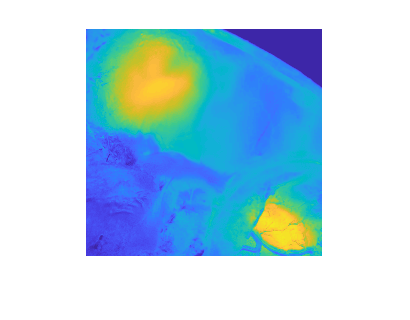

xcorrFiles = loadFileList([dname '*_corr.mat']);
load(xcorrFiles{5});
imagesc(fliplr(imcrop(corrmat,[10 30 235 256])));
caxis([0 1]);
box off;
axis off;
%figQuality(figh,gca,[1.238 1.312]);
%set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig(['.\EPS Panels\CorrEx.eps'], '-eps');

## Panel C

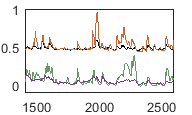


% file = 'M:\Bergles Lab Data\Projects\In vivo imaging\Auditory Cortex and IC Imaging\Downsample\Experiment-820_resampled_corrdfof.mat';
load(file);
acCol = [204 102 51]/255;
vcCol = [102 153 102]/255;
scCol = [126 47 142]/255;

%%dfOF
h = figure;
h.Units = 'inches';
h.Position = [5 5 2 1.2];
plot(ICsignal+.45,'k');
hold on;
plot(ACsignal+.45,'Color',acCol);
plot(VCsignal,'Color',vcCol);
plot(smooth((SCsignal)*2),'Color',scCol);
xlim([1400 2600]);
ylim([-0.1 1]);
set(gcf, 'Renderer', 'Painters');


%%Initialize

## Get all the averages

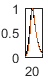


dname = 'M:\Bergles Lab Data\Projects\In vivo imaging\Auditory Cortex and IC Imaging\Downsample\Test\';
cd(dname);
list = dir('*_corrdfof.mat');
m = size(list,1);
corrx_tot =[];
corr_brain = [];
lag_tot = [];
figure;
ACavg = [];
VCavg = [];
ICavg = [];
SCavg = [];

for i=1:m
    load(list(i).name);
    ACavg(:,i) = mean(ACpeaks,2);
    VCavg(:,i) = mean(VCpeaks,2);
    ICavg(:,i) = mean(ICpeaks,2);
    SCavg(:,i) = mean(SCpeaks,2);
end
meanIC = mean(ICavg,2);
meanAC = mean(ACavg,2);
meanVC = mean(VCavg,2);
meanSC = mean(SCavg,2);

ICnorm = (meanIC-min(meanIC))/(max(meanIC)-min(meanIC));
ACnorm = (meanAC-min(meanAC))/(max(meanAC)-min(meanAC));
%VCnormVCnormVCnorm
%SCnormSCnormSCnorm

%colors
acCol = [204 102 51]/255;

h = figure; plot(ICnorm,'-k','MarkerSize',2); hold on; plot(ACnorm,'Color',acCol); 
%plot(ICnorm,'.','k'); %plot(ACnorm,'.','Color',acCol); 
h.Units = 'inches';
h.Position = [5 5 .5 0.82];
xlim([5 45]);

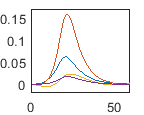

%axis off

%plot(VCnorm); plot(SCnorm); 

h = figure; plot(mean(ICavg,2)-mean(ICavg(1,:),2)); hold on; plot(mean(ACavg,2)-mean(ACavg(1,:),2)); 
plot(mean(VCavg,2)-mean(VCavg(1,:),2)); plot(mean(SCavg,2)-mean(SCavg(1,:),2)); 
h.Units = 'inches';
h.Position = [5 5 1.5 1.2];
xlim([0 60]);
ylim([-0.02 .17]);

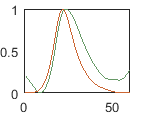


%%trigger off of SC
m = size(list,1);
ACavg = [];
VCavg = [];
ICavg = [];
SCavg = [];
for i=1:m
    load(list(i).name);
    ACavg(:,i) = mean(ACpeaks,2);
    VCavg(:,i) = mean(VCpeaks,2);
    ICavg(:,i) = mean(ICpeaks,2);
    SCavg(:,i) = mean(SCpeaks,2);
end
meanIC = mean(ICavg,2);
meanAC = mean(ACavg,2);
meanVC = mean(VCavg,2);
meanSC = mean(SCavg,2);

ICnorm = (meanIC-min(meanIC))/(max(meanIC)-min(meanIC));
ACnorm = (meanAC-min(meanAC))/(max(meanAC)-min(meanAC));
VCnorm = (meanVC-min(meanVC))/(max(meanVC)-min(meanVC));
SCnorm = (meanSC-min(meanSC))/(max(meanSC)-min(meanSC));

%colors
acCol = [204 102 51]/255;
vcCol = [102 153 102]/255;
scCol = [126 47 142]/255;

h = figure; plot(VCnorm,'Color',vcCol); hold on; plot(ACnorm,'Color',acCol); 
h.Units = 'inches';
h.Position = [5 5 1.5 1.2];
xlim([0 60]);

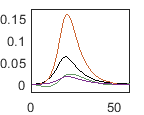


%plot(VCnorm); plot(SCnorm); 

h = figure; plot(mean(ICavg,2)-mean(ICavg(1,:),2),'k'); hold on; plot(mean(ACavg,2)-mean(ACavg(1,:),2),'Color',acCol); 
plot(mean(VCavg,2)-mean(VCavg(1,:),2),'Color', vcCol); plot(mean(SCavg,2)-mean(SCavg(1,:),2),'Color', scCol); 
h.Units = 'inches';
h.Position = [5 5 1.5 1.2];
xlim([0 60]);
ylim([-0.02 .17]);

## Correlation matrix

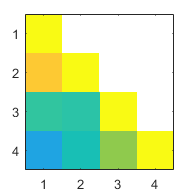

dname = '.\Data\IC and A1 Imaging\Downsample\Test\';
list = dir([dname '*_corrdfof.mat']);
m = size(list,1);
corr_tot =[];

for i=1:m
    load([dname list(i).name]);
    corr_tot(:,:,i) = corr([ICsignal', ACsignal', SCsignal', VCsignal']) .* [1 0 0 0; 1 1 0 0; 1 1 1 0; 1 1 1 1];
end

h = figure; imagesc(mean(corr_tot,3));
p_alt = parula;
p_alt(1,:) = [1 1 1];
colormap(p_alt);
caxis([0 1]);
h.Units = 'inches';
h.Position = [5 5 2 2];

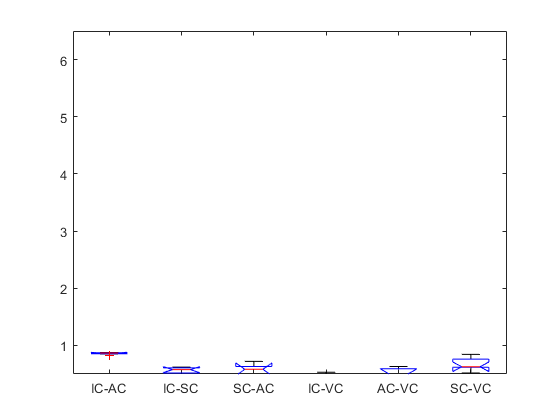


[p, t, st] = anova1([squeeze(corr_tot(2,1,:)) squeeze(corr_tot(3,1,:)) squeeze(corr_tot(3,2,:)) squeeze(corr_tot(4,1,:)) squeeze(corr_tot(4,2,:)) squeeze(corr_tot(4,3,:))],...
                     {'IC-AC', 'IC-SC', 'SC-AC', 'IC-VC','AC-VC', 'SC-VC'});

c =     1.0000    2.0000    0.1664    0.3105    0.4545    0.0000
    1.0000    3.0000    0.1704    0.3144    0.4585    0.0000
    1.0000    4.0000    0.3409    0.4850    0.6291    0.0000
    1.0000    5.0000    0.2085    0.3526    0.4966    0.0000
    1.0000    6.0000    0.0419    0.1859    0.3300    0.0052
    2.0000    3.0000   -0.1401    0.0040    0.1480    1.0000
    2.0000    4.0000    0.0305    0.1746    0.3186    0.0100
    2.0000    5.0000   -0.1020    0.0421    0.1862    0.9491
    2.0000    6.0000   -0.2686   -0.1245    0.0196    0.1234
    3.0000    4.0000    0.0265    0.1706    0.3146    0.0125


means =     0.8605    0.0339
    0.5501    0.0339
    0.5461    0.0339
    0.3755    0.0339
    0.5080    0.0339
    0.6746    0.0339


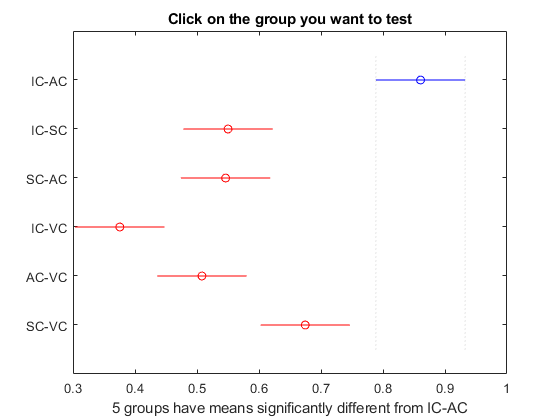

[c, means] = multcompare(st)

raw = [squeeze(corr_tot(2,1,:)) squeeze(corr_tot(3,1,:)) squeeze(corr_tot(3,2,:)) squeeze(corr_tot(4,1,:)) squeeze(corr_tot(4,2,:)) squeeze(corr_tot(4,3,:))];
means_sterrs = [mean(raw,1); sterr(raw,1)];
    


## Left Right Comparison

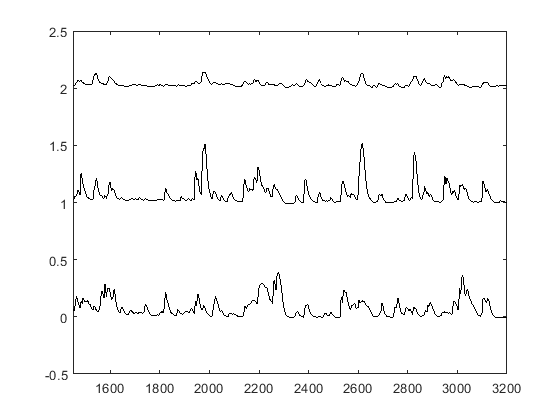

file = 'M:\Bergles Lab Data\Projects\In vivo imaging\Auditory Cortex and IC Imaging\Downsample\Experiment-820_resampled_corrdfof.mat';
load(file);
%%dfOF
figure;
plot(ICsignal+2,'k');
hold on;
plot(ACsignal+1,'k');
plot(VCsignal,'k');
xlim([1450 3200]);
set(gcf, 'Renderer', 'Painters');

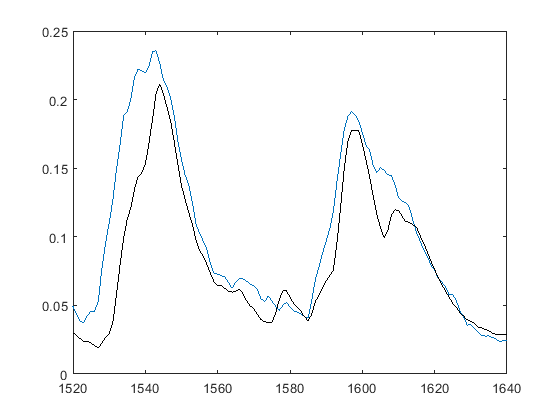


figure;
figure;
plot(ICsignal*2-.02);
hold on;
plot(ACsignal,'k');
xlim([1520 1640]);

## Cortex Ablation Comparisons

M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-1328_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 93

width = 14.3597

tempPkData =   100.0000    0.1690  100.0000    0.1070    0.0620    2.0000    1.0000
  203.0000    0.0198  203.0000    0.0136    0.0062    2.0000    1.0000
  229.0000    0.0476  229.0000    0.0260    0.0217    2.0000    1.0000
  331.0000    0.1321  328.0000    0.1129    0.0192    1.0000    1.0000
  374.0000    0.0437  374.0000    0.0053    0.0384    2.0000    1.0000
  396.0000    0.0477  399.0000    0.0477    0.0000    1.0000    1.0000
  498.0000    0.0836  498.0000    0.0307    0.0528    2.0000    1.0000
  533.0000    0.0491  536.0000    0.0367    0.0124    1.0000    1.0000
  700.0000    0.0844  700.0000    0.0499    0.0345    2.0000    1.0000
  744.0000    0.0571  744.0000    0.0066    0.0505    2.0000    1.0000


LIC: 140 peaks total, 93 corresponding RIC peaks.
RIC: 140 peaks total, 93 corresponding LIC peaks.
Mean RIC amplitude: 0.084861
Mean LIC amplitude: 0.089041
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-1328_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-652_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 61

width = 19.5007

tempPkData =     6.0000    0.1767    6.0000    0.0993    0.0774    2.0000    1.0000
   32.0000    0.1649   35.0000    0.0909    0.0739    1.0000    1.0000
   72.0000    0.1588   75.0000    0.1397    0.0191    1.0000    1.0000
  112.0000    0.0596  112.0000    0.0355    0.0241    2.0000    1.0000
  183.0000    0.1668  178.0000    0.1084    0.0584    1.0000    1.0000
  301.0000    0.0413  301.0000   -0.0003    0.0416    2.0000    1.0000
  387.0000    0.0935  387.0000    0.0871    0.0064    3.0000    1.0000
  406.0000    0.2413  407.0000    0.1746    0.0667    1.0000    1.0000
  585.0000    0.0341  585.0000    0.0094    0.0247    2.0000    1.0000
  617.0000    0.2313  616.0000    0.0729    0.1584    1.0000    1.0000


LIC: 128 peaks total, 75 corresponding RIC peaks.
RIC: 116 peaks total, 75 corresponding LIC peaks.
Mean RIC amplitude: 0.086317
Mean LIC amplitude: 0.1074
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-652_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-689_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 63

width = 17.6740

tempPkData =    29.0000    0.0626   29.0000    0.0179    0.0446    2.0000    1.0000
   57.0000    0.1901   62.0000    0.1014    0.0886    1.0000    1.0000
  178.0000    0.0519  181.0000    0.0295    0.0224    1.0000    1.0000
  219.0000    0.1102  218.0000    0.0635    0.0467    1.0000    1.0000
  271.0000    0.0672  278.0000    0.0491    0.0181    1.0000    1.0000
  382.0000    0.0789  380.0000    0.0380    0.0409    1.0000    1.0000
  536.0000    0.0990  536.0000    0.0638    0.0352    2.0000    1.0000
  623.0000    0.0896  622.0000    0.0438    0.0458    1.0000    1.0000
  673.0000    0.0601  673.0000    0.0521    0.0079    2.0000    1.0000
  733.0000    0.2633  738.0000    0.1733    0.0900    1.0000    1.0000


LIC: 129 peaks total, 98 corresponding RIC peaks.
RIC: 121 peaks total, 98 corresponding LIC peaks.
Mean RIC amplitude: 0.096711
Mean LIC amplitude: 0.11213
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-689_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-690_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 83

width = 17.5189

tempPkData =   104.0000    0.0645  104.0000    0.0578    0.0067    1.0000    1.0000
  299.0000    0.2125  298.0000    0.1344    0.0781    1.0000    1.0000
  323.0000    0.0867  323.0000    0.0816    0.0051    3.0000    1.0000
  462.0000    0.0384  462.0000    0.0142    0.0242    2.0000    1.0000
  518.0000    0.1866  508.0000    0.1634    0.0232    1.0000    1.0000
  760.0000    0.0938  758.0000    0.0812    0.0125    1.0000    1.0000
  811.0000    0.0311  811.0000    0.0104    0.0207    2.0000    1.0000
  828.0000    0.0372  828.0000    0.0368    0.0004    3.0000    1.0000
  841.0000    0.0481  841.0000    0.0348    0.0134    2.0000    1.0000
  946.0000    0.0926  943.0000    0.0708    0.0219    1.0000    1.0000


LIC: 115 peaks total, 83 corresponding RIC peaks.
RIC: 116 peaks total, 83 corresponding LIC peaks.
Mean RIC amplitude: 0.089565
Mean LIC amplitude: 0.085749
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-690_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-693_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 77

width = 17.4616

tempPkData =   198.0000    0.0448  198.0000    0.0369    0.0079    2.0000    1.0000
  227.0000    0.0212  227.0000    0.0191    0.0021    3.0000    1.0000
  250.0000    0.0257  250.0000    0.0071    0.0186    2.0000    1.0000
  314.0000    0.1310  312.0000    0.0671    0.0639    1.0000    1.0000
  386.0000    0.2059  386.0000    0.0872    0.1187    2.0000    1.0000
  458.0000    0.1750  459.0000    0.1731    0.0019    1.0000    1.0000
  539.0000    0.0943  543.0000    0.0506    0.0438    1.0000    1.0000
  573.0000    0.0523  573.0000    0.0251    0.0272    2.0000    1.0000
  658.0000    0.0643  658.0000    0.0531    0.0112    1.0000    1.0000
  681.0000    0.0217  681.0000    0.0011    0.0206    2.0000    1.0000


LIC: 110 peaks total, 73 corresponding RIC peaks.
RIC: 109 peaks total, 73 corresponding LIC peaks.
Mean RIC amplitude: 0.087308
Mean LIC amplitude: 0.086088
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-693_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-712_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 77

width = 14.8873

tempPkData =    1.0e+03 *

    0.0390    0.0001    0.0380    0.0001    0.0000    0.0010    0.0010
    0.1480    0.0002    0.1440    0.0001    0.0001    0.0010    0.0010
    0.2610    0.0000    0.2580    0.0000    0.0000    0.0010    0.0010
    0.3970    0.0001    0.3980    0.0000    0.0000    0.0010    0.0010
    0.5360    0.0001    0.5400    0.0000    0.0000    0.0010    0.0010
    0.7540    0.0001    0.7540    0.0000    0.0001    0.0020    0.0010
    0.7850    0.0000    0.7850    0.0000    0.0000    0.0020    0.0010
    0.8480    0.0000    0.8480    0.0000    0.0000    0.0020    0.0010
    1.0540    0.0001    1.0530    0.0000    0.0001    0.0010    0.0010
    1.0900    0.0001    1.0880    0.0000    0.0000    0.0010    0.0010


LIC: 129 peaks total, 100 corresponding RIC peaks.
RIC: 130 peaks total, 100 corresponding LIC peaks.
Mean RIC amplitude: 0.085877
Mean LIC amplitude: 0.086936
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-712_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-993_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 67

width = 18.3981

tempPkData =    38.0000    0.0599   38.0000    0.0566    0.0033    1.0000    1.0000
  114.0000    0.0745  112.0000    0.0282    0.0464    1.0000    1.0000
  285.0000    0.0487  285.0000    0.0268    0.0219    2.0000    1.0000
  314.0000    0.2081  320.0000    0.1670    0.0411    1.0000    1.0000
  344.0000    0.1680  344.0000    0.0793    0.0887    2.0000    1.0000
  432.0000    0.0125  432.0000    0.0008    0.0117    2.0000    1.0000
  481.0000    0.0930  481.0000    0.0582    0.0347    1.0000    1.0000
  508.0000    0.1233  508.0000    0.1003    0.0230    1.0000    1.0000
  558.0000    0.0811  558.0000    0.0236    0.0575    2.0000    1.0000
  595.0000    0.0565  590.0000    0.0323    0.0242    1.0000    1.0000


LIC: 124 peaks total, 90 corresponding RIC peaks.
RIC: 132 peaks total, 90 corresponding LIC peaks.
Mean RIC amplitude: 0.085744
Mean LIC amplitude: 0.098714
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-993_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF


counts =      4    25    29    23     4     4     5     0     6    26    27    20     9     2     3     0
     0    20    29    27    16    12     4     0     3    24    15     9     5     4     1     0
     1    20    28    11    14     8     4     3     4    21    11    12    13     2     0     0
     3    25    13     6    10     8     0     0     3    28    26    12     9     2     2     1
     3    22    23    11     5     5     0     0     5    23    20    18     8     1     2     0
     4    25    27    15     2     7     1     1     2    32    20     9    11     2     1     0
     1    32    28    14    11    12     1     0     1    26    16    12    10     2     0     0


Lcounts =    24.1429   25.2857   15.2857    8.8571    8.0000    2.1429    0.5714


Rcounts =    25.7143   19.2857   13.1429    9.2857    2.1429    1.2857    0.1429


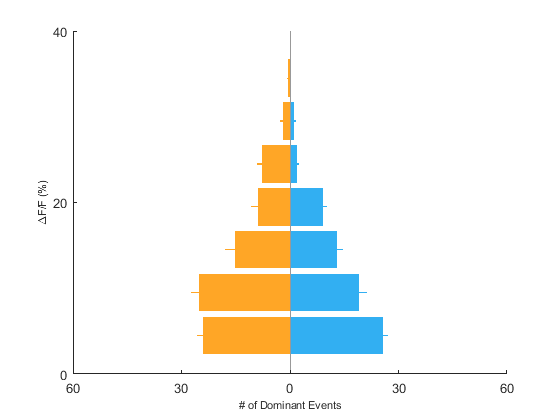

ablationsFiles = loadFileList('.\Data\Cortical Ablations\*\*ICinfo16_dFoF.mat');
[ctxabl_stats, figh] = groupData_histograms(ablationsFiles);

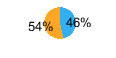

[m,n] = size(ctxabl_stats);

  
stats_tot = table();
stats_tot = ctxabl_stats;

pieSize = [0.6 0.6];
[avg, sd, fg] =LRpie(ctxabl_stats);
figQuality(gcf,gca,pieSize);
print(['.\EPS Panels\ablation_Pi.eps'],'-depsc')

%[(1-avg) * 360 - 180 - sd * 360, (1-avg) * 360 - 180 + sd * 360] %% error circle angles for coreldraw, 1 px width, same size as circle




meanAmpl = mean(stats_tot{:,8:9}/10);
stdAmpl = sterr(stats_tot{:,8:9}/10,1)

stdAmpl =     0.5916    0.4358


std(stats_tot{:,8:9}/10,[],1)

ans =     1.5651    1.1530



figure;
[h, p] = ttest2(stats_tot{:,8}/10, stats_tot{:,9}/10)

h = 0

p = 0.1243

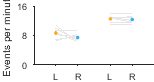

m = size(stats_tot,1);
line([ones(1,m); 2*ones(1,m)], [stats_tot{:,8}/10, stats_tot{:,9}/10]','Color',lgray); hold on;
errorbar([1], meanAmpl(1), stdAmpl(1),'LineStyle', 'none','Color',lt_org,'CapSize',0,'Marker','.','MarkerSize',8);
errorbar([2], meanAmpl(2), stdAmpl(2),'LineStyle', 'none','Color',lt_blue,'CapSize',0,'Marker','.','MarkerSize',8);


meanAmpl = mean(stats_tot{:,1:2}/10);
stdAmpl = sterr(stats_tot{:,1:2}/10,1);
m = size(stats_tot,1);
line([3.5*ones(1,m); 4.5*ones(1,m)], [stats_tot{:,1}/10, stats_tot{:,2}/10]','Color',lgray); hold on;
errorbar([3.5], meanAmpl(1), stdAmpl(1),'LineStyle', 'none','Color',lt_org,'CapSize',0,'Marker','.','MarkerSize',8);
errorbar([4.5], meanAmpl(2), stdAmpl(2),'LineStyle', 'none','Color',lt_blue,'CapSize',0,'Marker','.','MarkerSize',8);
xlim([0 5.5]);
ylim([0 16]);
yticks([0 8 16]);
xticks([1 2 3.5 4.5]);
xticklabels({'L','R','L','R'});
ylabel('Events per minute');
figQuality(gcf,gca,[1.6 .85]);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig('.\EPS Panels\ctxabl_freq.eps',gcf);




figure;
[h, p] = ttest2(stats_tot{:,4}*100, stats_tot{:,5}*100)

h = 0

p = 0.1359

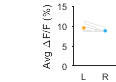

meanAmpl = mean(stats_tot{:,4:5}*100);
stdAmpl = sterr(stats_tot{:,4:5}*100,1);
m = size(stats_tot,1);
line([ones(1,m); 2*ones(1,m)], [stats_tot{:,4}*100, stats_tot{:,5}*100]','Color',lgray); hold on;
errorbar([1], meanAmpl(1), stdAmpl(1),'LineStyle', 'none','Color',lt_org,'CapSize',0,'Marker','.','MarkerSize',8);
errorbar([2], meanAmpl(2), stdAmpl(2),'LineStyle', 'none','Color',lt_blue,'CapSize',0,'Marker','.','MarkerSize',8);
xlim([0.5 2.5]);
ylim([0 15]);
xticks([1 2])
xticklabels({'L','R'});
ylabel('Avg \DeltaF/F (%)');
figQuality(gcf,gca,[.55 .85]);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig('.\EPS Panels\ctxabl_ampl.eps',gcf);



%half-widths
figure;
[avgWave, stErr, half_width, ampl] = waveform2LR(ablationsFiles);
meanAmpl = mean(half_width/10);
stdAmpl = sterr(half_width/10,1)

stdAmpl =     0.0243    0.0234


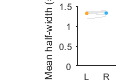

m = size(stats_tot,1);
line([ones(1,m); 2*ones(1,m)], [half_width(:,1)/10, half_width(:,2)/10]','Color',lgray); hold on;
errorbar([1], meanAmpl(1), stdAmpl(1),'LineStyle', 'none','Color',lt_org,'CapSize',0,'Marker','.','MarkerSize',8);
errorbar([2], meanAmpl(2), stdAmpl(2),'LineStyle', 'none','Color',lt_blue,'CapSize',0,'Marker','.','MarkerSize',8);
ylim([0 1.5]);
yticks([0:.5:1.5]);
xlim([0.5 2.5]);
xticks([1 2])
xticklabels({'L','R'});
ylabel('Mean half-width (s)');
figQuality(gcf,gca,[.55 .85]);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig('.\EPS Panels\ctxabl_hws.eps',gcf);

## Plots

r_locs =     13
    41
    76
   168
   189
   274
   445
   479
   565
   605


r_locs =    158
   244
   377
   466
   518
   562
   644
   787
   902
   946


r_locs =     84
   122
   159
   304
   353
   512
   556
   648
   786
   916


r_locs =     60
   189
   210
   258
   270
   323
   395
   424
   508
   576


r_locs =     74
   112
   198
   227
   288
   334
   375
   437
   459
   498


r_locs =     81
   102
   113
   178
   290
   301
   347
   368
   469
   499


r_locs =    212
   241
   320
   389
   412
   481
   639
   670
   713
   765


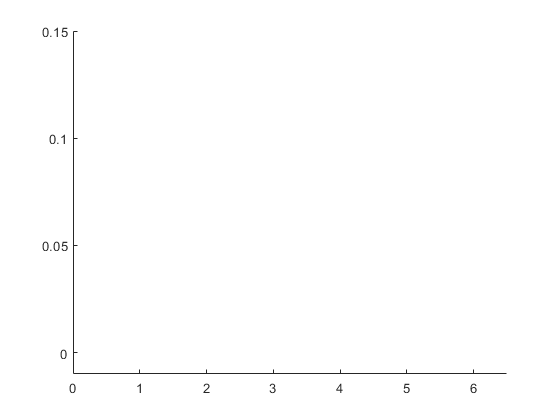

%half-widths
[avgWave, stErr, half_width, ampl] = waveform2LR(ablationsFiles);

compare2C(stats_tot{:,4}*100,stats_tot{:,5}*100,{'L','R'},'Avg \DeltaF/F (%)',[1 1.5],[15 10], lt_org, lt_blue);

    0.2251



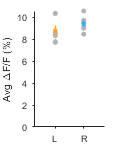

%ylim([0 75]);
%yticks([0:25:75]);   
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\spikesPerBurst.eps',gcf);

## Cross Correlation

dname = '.\Data\IC and A1 Imaging\Downsample\'

dname = '.\Data\IC and A1 Imaging\Downsample\'

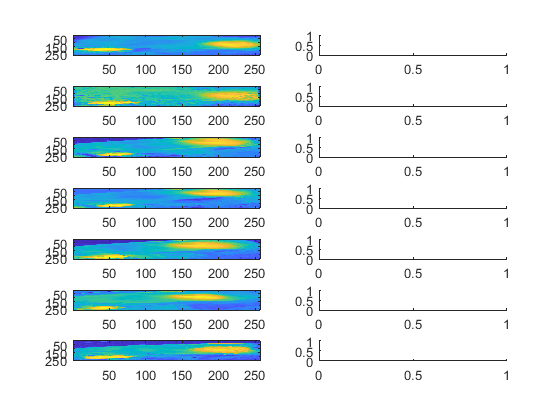

ans =            1        6048


temp =     1.0000    0.8735    0.3213
    0.8735    1.0000    0.4620
    0.3213    0.4620    1.0000


ans =            1        6048


temp =     1.0000    0.8796   -0.0131
    0.8796    1.0000    0.0035
   -0.0131    0.0035    1.0000


ans =            1        5998


temp =     1.0000    0.8533    0.0897
    0.8533    1.0000    0.0582
    0.0897    0.0582    1.0000


ans =            1        5997


temp =     1.0000    0.8652    0.0716
    0.8652    1.0000    0.0184
    0.0716    0.0184    1.0000


ans =            1        5998


temp =     1.0000    0.8635    0.0458
    0.8635    1.0000    0.0490
    0.0458    0.0490    1.0000


ans =            1        5998


temp =     1.0000    0.8234   -0.0094
    0.8234    1.0000   -0.0131
   -0.0094   -0.0131    1.0000


ans =            1        5998


temp =     1.0000    0.8686   -0.0034
    0.8686    1.0000   -0.0053
   -0.0034   -0.0053    1.0000


xcorrFiles = loadFileList([dname '*_corr.mat']);
m = size(xcorrFiles,1);
corrx_tot =[];
corr_brain = [];
lag_tot = [];
figure;
for i=1:m
    load(xcorrFiles{i});
    subplot(m,2,1+(2*(i-1)));
    imagesc(corrmat);
    subplot(m,2,2+(2*(i-1)));
    %%contour(imgaussfilt(corrmat,3),[.6 .6]);
    size(ICsignal)
    ICsignal = ICsignal(:,1:5997);
    ACsignal =  ACsignal(:,1:5997);
    if exist('VCsignal')
        VCsignal =  VCsignal(:,1:5997);
    else
        VCsignal = V1signal(:,1:5997);
    end
    ICsignalMean = mean(ICsignal);
    ACsignalMean = mean(ACsignal);
    
    [corrx, lag] = xcorr(ICsignal-ICsignalMean, ACsignal-ACsignalMean,'coeff');
    %[corrx, lag] = xcorr(ICsignal-ICsignalMean, ACsignal-ACsignalMean,'unbiased');
    corrx_tot(i,:) = corrx;
    lag_tot(i,:) = lag/10;
    mean_corrx = mean(corrx_tot);
    std_corrx = std(corrx_tot,1);
    temp = corr([ICsignal',ACsignal',VCsignal'])
    coor_brain(i,:) = temp(1,2:3);
end

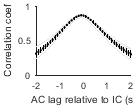


lgray = [0.9 0.9 0.9];
h =figure; h.Units = 'inches'; h.Position = [5 5 1.75 1.5]; markSize = 5;
plot(lag_tot', corrx_tot','Color',lgray); hold on; 
%scatter(lag_tot(:), corrx_tot(:),markSize*0.6,lgray,'filled');

plot(lag_tot(1,:),mean_corrx,'.','Color',[0 0 0],'MarkerSize',markSize)
errorbar(lag_tot(1,:),mean_corrx,std_corrx,'CapSize',0,'Color',[0 0 0],'LineStyle','none');
xlim([-2 2]);
ylim([0 1]);
yticks([0 0.5 1])
xticks(-2:1:2);
xlabel('AC lag relative to IC (s)'); ylabel('Correlation coef');
figQuality(gcf,gca,[1.4 1.1]);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig(['.\EPS Panels\xCorrelation.eps'], '-eps', '-nocrop');


[h,p] = ttest(corrx_tot(:,5996),corrx_tot(:,5997))



## LR Comparison

%%load 
ablationsFiles = loadFileList('.\Data\Cortical Ablations\*\*ICmovs_peaks_dFoF_remflash.mat');
                
[groupHistoL,groupHistoR,totalEvents,individualStats, lhistosing, rhistosing] = analGroupDataLR(ablationsFiles,0)

## plot

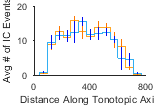


    
edges = 1:7:125;
edgesX = 4.5:7:120;
shift = 0;
lcounts = mean(lhistosing,2);
rcounts = mean(rhistosing,2);
lcountserr = std(lhistosing,1,2)/sqrt(size(lhistosing,2));
rcountserr = std(rhistosing,1,2)/sqrt(size(rhistosing,2));

histogram('BinEdges',edges+shift,'BinCounts',lcounts,'EdgeColor',lt_org,'FaceColor','none','DisplayStyle','stairs','FaceAlpha',1); hold on;
histogram('BinEdges',edges,'BinCounts',rcounts,'EdgeColor',lt_blue,'FaceColor','none','DisplayStyle','stairs','FaceAlpha',1);
line([edgesX+shift; edgesX+shift],[lcounts' + lcountserr';lcounts' - lcountserr'],'Color',dk_org);
line([edgesX; edgesX],[rcounts' + rcountserr';rcounts' - rcountserr'],'Color',dk_blue);
xlim([10 110])
xticks([10 60 110])
xticklabels({'0','400','800'});
yticks([0 10 20]);
ylabel('Avg # of IC Events');
xlabel('Distance Along Tonotopic Axis')
figQuality(gcf,gca,[1.6 1.1]);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig(['.\EPS Panels\AblationGroupSpatialDistribution.eps'], '-eps', '-nocrop');

## Panel H

ctxAblFile = '.\Data\Cortical Ablations\Experiment-1328_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat';
load(ctxAblFile);
[filePath name ext] = fileparts(ctxAblFile);
[stats, pkData] = findICpeaksdFoF(ICsignal,filePath,'dFoF',0);

Rdom = 100

width = 14.1529

tempPkData =   101.0000    0.1708  101.0000    0.1025    0.0683    2.0000    1.0000
  204.0000    0.0324  204.0000    0.0105    0.0218    2.0000    1.0000
  229.0000    0.0553  229.0000    0.0257    0.0296    2.0000    1.0000
  313.0000    0.0842  313.0000    0.0361    0.0481    2.0000    1.0000
  332.0000    0.1246  328.0000    0.1167    0.0079    1.0000    1.0000
  375.0000    0.0402  375.0000    0.0059    0.0343    2.0000    1.0000
  396.0000    0.0494  399.0000    0.0484    0.0011    1.0000    1.0000
  498.0000    0.0908  498.0000    0.0320    0.0587    2.0000    1.0000
  532.0000    0.0599  536.0000    0.0380    0.0219    1.0000    1.0000
  700.0000    0.1010  700.0000    0.0511    0.0499    2.0000    1.0000


LIC: 128 peaks total, 86 corresponding RIC peaks.
RIC: 145 peaks total, 86 corresponding LIC peaks.
Mean RIC amplitude: 0.084744
Mean LIC amplitude: 0.084494
.\Data\Cortical Ablations\Experiment-1328_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF


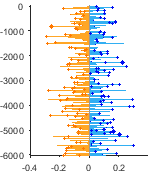

[figh1, figh2] = lollipopPlot(pkData);
set(0,'CurrentFigure', figh1);
figQuality(figh1,gca,[1.6 1.8]);
export_fig(['.\EPS Panels\ctxAblex.eps'], '-eps', '-nocrop')

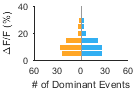


set(0,'CurrentFigure', figh2)
figQuality(figh2,gca,[1.4 .95]);
export_fig(['.\EPS Panels\ctxAblHisto.eps'], '-eps', '-nocrop')

## Panel I

ablationsFiles = loadFileList('.\Data\Cortical Ablations\*\*ICinfo16_dFoF.mat');
[stats, figh, counts] = groupData_histograms(ablationsFiles);

M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-1328_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 93

width = 14.3597

tempPkData =   100.0000    0.1690  100.0000    0.1070    0.0620    2.0000    1.0000
  203.0000    0.0198  203.0000    0.0136    0.0062    2.0000    1.0000
  229.0000    0.0476  229.0000    0.0260    0.0217    2.0000    1.0000
  331.0000    0.1321  328.0000    0.1129    0.0192    1.0000    1.0000
  374.0000    0.0437  374.0000    0.0053    0.0384    2.0000    1.0000
  396.0000    0.0477  399.0000    0.0477    0.0000    1.0000    1.0000
  498.0000    0.0836  498.0000    0.0307    0.0528    2.0000    1.0000
  533.0000    0.0491  536.0000    0.0367    0.0124    1.0000    1.0000
  700.0000    0.0844  700.0000    0.0499    0.0345    2.0000    1.0000
  744.0000    0.0571  744.0000    0.0066    0.0505    2.0000    1.0000


LIC: 140 peaks total, 93 corresponding RIC peaks.
RIC: 140 peaks total, 93 corresponding LIC peaks.
Mean RIC amplitude: 0.084861
Mean LIC amplitude: 0.089041
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-1328_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-652_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 61

width = 19.5007

tempPkData =     6.0000    0.1767    6.0000    0.0993    0.0774    2.0000    1.0000
   32.0000    0.1649   35.0000    0.0909    0.0739    1.0000    1.0000
   72.0000    0.1588   75.0000    0.1397    0.0191    1.0000    1.0000
  112.0000    0.0596  112.0000    0.0355    0.0241    2.0000    1.0000
  183.0000    0.1668  178.0000    0.1084    0.0584    1.0000    1.0000
  301.0000    0.0413  301.0000   -0.0003    0.0416    2.0000    1.0000
  387.0000    0.0935  387.0000    0.0871    0.0064    3.0000    1.0000
  406.0000    0.2413  407.0000    0.1746    0.0667    1.0000    1.0000
  585.0000    0.0341  585.0000    0.0094    0.0247    2.0000    1.0000
  617.0000    0.2313  616.0000    0.0729    0.1584    1.0000    1.0000


LIC: 128 peaks total, 75 corresponding RIC peaks.
RIC: 116 peaks total, 75 corresponding LIC peaks.
Mean RIC amplitude: 0.086317
Mean LIC amplitude: 0.1074
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-652_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-689_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 63

width = 17.6740

tempPkData =    29.0000    0.0626   29.0000    0.0179    0.0446    2.0000    1.0000
   57.0000    0.1901   62.0000    0.1014    0.0886    1.0000    1.0000
  178.0000    0.0519  181.0000    0.0295    0.0224    1.0000    1.0000
  219.0000    0.1102  218.0000    0.0635    0.0467    1.0000    1.0000
  271.0000    0.0672  278.0000    0.0491    0.0181    1.0000    1.0000
  382.0000    0.0789  380.0000    0.0380    0.0409    1.0000    1.0000
  536.0000    0.0990  536.0000    0.0638    0.0352    2.0000    1.0000
  623.0000    0.0896  622.0000    0.0438    0.0458    1.0000    1.0000
  673.0000    0.0601  673.0000    0.0521    0.0079    2.0000    1.0000
  733.0000    0.2633  738.0000    0.1733    0.0900    1.0000    1.0000


LIC: 129 peaks total, 98 corresponding RIC peaks.
RIC: 121 peaks total, 98 corresponding LIC peaks.
Mean RIC amplitude: 0.096711
Mean LIC amplitude: 0.11213
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-689_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-690_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 83

width = 17.5189

tempPkData =   104.0000    0.0645  104.0000    0.0578    0.0067    1.0000    1.0000
  299.0000    0.2125  298.0000    0.1344    0.0781    1.0000    1.0000
  323.0000    0.0867  323.0000    0.0816    0.0051    3.0000    1.0000
  462.0000    0.0384  462.0000    0.0142    0.0242    2.0000    1.0000
  518.0000    0.1866  508.0000    0.1634    0.0232    1.0000    1.0000
  760.0000    0.0938  758.0000    0.0812    0.0125    1.0000    1.0000
  811.0000    0.0311  811.0000    0.0104    0.0207    2.0000    1.0000
  828.0000    0.0372  828.0000    0.0368    0.0004    3.0000    1.0000
  841.0000    0.0481  841.0000    0.0348    0.0134    2.0000    1.0000
  946.0000    0.0926  943.0000    0.0708    0.0219    1.0000    1.0000


LIC: 115 peaks total, 83 corresponding RIC peaks.
RIC: 116 peaks total, 83 corresponding LIC peaks.
Mean RIC amplitude: 0.089565
Mean LIC amplitude: 0.085749
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-690_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-693_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 77

width = 17.4616

tempPkData =   198.0000    0.0448  198.0000    0.0369    0.0079    2.0000    1.0000
  227.0000    0.0212  227.0000    0.0191    0.0021    3.0000    1.0000
  250.0000    0.0257  250.0000    0.0071    0.0186    2.0000    1.0000
  314.0000    0.1310  312.0000    0.0671    0.0639    1.0000    1.0000
  386.0000    0.2059  386.0000    0.0872    0.1187    2.0000    1.0000
  458.0000    0.1750  459.0000    0.1731    0.0019    1.0000    1.0000
  539.0000    0.0943  543.0000    0.0506    0.0438    1.0000    1.0000
  573.0000    0.0523  573.0000    0.0251    0.0272    2.0000    1.0000
  658.0000    0.0643  658.0000    0.0531    0.0112    1.0000    1.0000
  681.0000    0.0217  681.0000    0.0011    0.0206    2.0000    1.0000


LIC: 110 peaks total, 73 corresponding RIC peaks.
RIC: 109 peaks total, 73 corresponding LIC peaks.
Mean RIC amplitude: 0.087308
Mean LIC amplitude: 0.086088
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-693_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-712_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 77

width = 14.8873

tempPkData =    1.0e+03 *

    0.0390    0.0001    0.0380    0.0001    0.0000    0.0010    0.0010
    0.1480    0.0002    0.1440    0.0001    0.0001    0.0010    0.0010
    0.2610    0.0000    0.2580    0.0000    0.0000    0.0010    0.0010
    0.3970    0.0001    0.3980    0.0000    0.0000    0.0010    0.0010
    0.5360    0.0001    0.5400    0.0000    0.0000    0.0010    0.0010
    0.7540    0.0001    0.7540    0.0000    0.0001    0.0020    0.0010
    0.7850    0.0000    0.7850    0.0000    0.0000    0.0020    0.0010
    0.8480    0.0000    0.8480    0.0000    0.0000    0.0020    0.0010
    1.0540    0.0001    1.0530    0.0000    0.0001    0.0010    0.0010
    1.0900    0.0001    1.0880    0.0000    0.0000    0.0010    0.0010


LIC: 129 peaks total, 100 corresponding RIC peaks.
RIC: 130 peaks total, 100 corresponding LIC peaks.
Mean RIC amplitude: 0.085877
Mean LIC amplitude: 0.086936
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-712_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-993_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF.mat


Rdom = 67

width = 18.3981

tempPkData =    38.0000    0.0599   38.0000    0.0566    0.0033    1.0000    1.0000
  114.0000    0.0745  112.0000    0.0282    0.0464    1.0000    1.0000
  285.0000    0.0487  285.0000    0.0268    0.0219    2.0000    1.0000
  314.0000    0.2081  320.0000    0.1670    0.0411    1.0000    1.0000
  344.0000    0.1680  344.0000    0.0793    0.0887    2.0000    1.0000
  432.0000    0.0125  432.0000    0.0008    0.0117    2.0000    1.0000
  481.0000    0.0930  481.0000    0.0582    0.0347    1.0000    1.0000
  508.0000    0.1233  508.0000    0.1003    0.0230    1.0000    1.0000
  558.0000    0.0811  558.0000    0.0236    0.0575    2.0000    1.0000
  595.0000    0.0565  590.0000    0.0323    0.0242    1.0000    1.0000


LIC: 124 peaks total, 90 corresponding RIC peaks.
RIC: 132 peaks total, 90 corresponding LIC peaks.
Mean RIC amplitude: 0.085744
Mean LIC amplitude: 0.098714
M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\Cortical Ablations\Experiment-993_P7_Snap25GC6s_AC_ablation\ICinfo16_dFoF


counts =      4    25    29    23     4     4     5     0     6    26    27    20     9     2     3     0
     0    20    29    27    16    12     4     0     3    24    15     9     5     4     1     0
     1    20    28    11    14     8     4     3     4    21    11    12    13     2     0     0
     3    25    13     6    10     8     0     0     3    28    26    12     9     2     2     1
     3    22    23    11     5     5     0     0     5    23    20    18     8     1     2     0
     4    25    27    15     2     7     1     1     2    32    20     9    11     2     1     0
     1    32    28    14    11    12     1     0     1    26    16    12    10     2     0     0


Lcounts =    24.1429   25.2857   15.2857    8.8571    8.0000    2.1429    0.5714


Rcounts =    25.7143   19.2857   13.1429    9.2857    2.1429    1.2857    0.1429


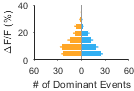

set(0,'CurrentFigure', figh);
set(gca,'LooseInset',get(gca,'TightInset')) ;
figQuality(figh,gca,[1.4 .95]);
export_fig(['.\EPS Panels\AblationGroupHisto.eps'], '-eps', '-nocrop');

## Analysis of # of correlated peaks

dname = '.\Data\IC and A1 Imaging\Downsample\'

dname = '.\Data\IC and A1 Imaging\Downsample\'

class = 3

class = 3

class = 5

class = 8

class = 3

class = 8

class = 3

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 5

class = 8

class = 8

class = 5

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 5

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 5

class = 8

class = 3

class = 3

class = 8

class = 5

class = 8

class = 8

class = 3

class = 5

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 8

class = 3

class = 5

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 3

class = 5

class = 8

class = 5

class = 8

class = 8

class = 3

class = 5

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 3

class = 3

class = 8

class = 5

class = 3

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 3

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 5

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 5

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 3

class = 5

class = 8

class = 8

class = 5

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 3

class = 3

class = 8

class = 5

class = 8

class = 8

class = 3

class = 5

class = 8

class = 8

class = 8

class = 8

class = 3

class = 3

class = 8

class = 8

class = 3

class = 8

class = 5

class = 8

class = 3

class = 8

class = 8

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 3

class = 5

class = 3

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 5

class = 8

class = 5

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 8

class = 8

class = 5

class = 8

class = 8

class = 5

class = 3

class = 5

class = 8

class = 3

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 3

class = 8

class = 8

class = 3

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 8

class = 5

class = 3

class = 8

class = 3

class = 8

class = 3

class = 8

class = 3

class = 5

class = 3

class = 8

class = 3

class = 8

class = 3

class = 8

class = 3

class = 5

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 5

class = 8

class = 3

class = 8

class = 3

class = 8

class = 3

class = 3

class = 5

class = 8

class = 8

class = 5

class = 3

class = 8

class = 3

class = 3

class = 3

class = 5

class = 8

class = 5

class = 8

class = 8

class = 3

class = 5

class = 3

class = 8

class = 3

class = 5

class = 8

class = 8

class = 8

class = 8

class = 3

class = 5

class = 8

class = 8

class = 8

class = 8

class = 5

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 5

class = 8

class = 3

class = 8

class = 3

class = 5

class = 8

class = 8

class = 8

class = 3

class = 8

class = 5

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 3

class = 5

class = 8

class = 8

class = 8

class = 8

class = 5

class = 3

class = 3

class = 8

class = 8

class = 5

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 5

class = 5

class = 8

class = 5

class = 8

class = 5

class = 3

class = 8

class = 3

class = 5

class = 8

class = 5

class = 3

class = 3

class = 8

class = 5

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 5

class = 5

class = 8

class = 3

class = 5

class = 8

class = 8

class = 3

class = 3

class = 5

class = 8

class = 3

class = 5

class = 5

class = 8

class = 3

class = 8

class = 5

class = 5

class = 8

class = 5

class = 8

class = 8

class = 3

class = 5

class = 8

class = 5

class = 3

class = 5

class = 8

class = 8

class = 5

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 5

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 3

class = 5

class = 3

class = 8

class = 5

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 5

class = 8

class = 5

class = 8

class = 5

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 5

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 5

class = 5

class = 8

class = 3

class = 8

class = 8

class = 3

class = 8

class = 5

class = 8

class = 5

class = 8

class = 5

class = 3

class = 5

class = 3

class = 5

class = 8

class = 8

class = 8

class = 8

class = 5

class = 3

class = 3

class = 8

class = 8

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 5

class = 3

class = 8

class = 5

class = 5

class = 8

class = 8

class = 5

class = 8

class = 3

class = 8

class = 8

class = 3

class = 3

class = 8

class = 3

class = 8

class = 8

class = 8

class = 5

class = 8

class = 8

class = 3

class = 8

class = 8

class = 3

class = 3

class = 5

class = 8

class = 8

class = 5

class = 8

class = 5

class = 8

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 5

class = 8

class = 5

class = 3

class = 5

class = 3

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 3

class = 8

class = 5

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 5

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 5

class = 3

class = 8

class = 5

class = 8

class = 3

class = 8

class = 3

class = 3

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 8

class = 3

class = 3

class = 5

class = 8

class = 8

class = 8

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 5

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 3

class = 8

class = 5

class = 5

class = 8

class = 8

class = 3

class = 8

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 5

class = 3

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 5

class = 8

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 3

class = 5

class = 5

class = 3

class = 3

class = 8

class = 5

class = 8

class = 8

class = 5

class = 8

class = 5

class = 3

class = 3

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 3

class = 3

class = 5

class = 5

class = 8

class = 5

class = 5

class = 8

class = 8

class = 8

class = 5

class = 8

class = 5

class = 3

class = 5

class = 5

class = 8

class = 5

class = 8

class = 8

class = 5

class = 3

class = 8

class = 8

class = 8

class = 8

class = 5

class = 3

class = 8

class = 8

class = 5

class = 8

class = 3

class = 5

class = 3

class = 8

class = 5

class = 3

class = 5

class = 8

class = 5

class = 3

class = 8

class = 5

class = 8

class = 8

class = 8

class = 5

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 5

class = 3

class = 5

class = 8

class = 3

class = 5

class = 5

class = 8

class = 8

class = 8

class = 3

class = 3

class = 8

class = 5

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 3

class = 8

class = 5

class = 8

class = 8

class = 3

class = 8

class = 3

class = 8

class = 3

class = 5

class = 3

class = 5

class = 3

class = 3

class = 8

class = 3

class = 3

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 3

class = 5

class = 8

class = 3

class = 8

class = 5

class = 8

class = 5

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 8

class = 8

class = 3

class = 3

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 3

class = 8

class = 3

class = 8

class = 3

class = 3

class = 8

class = 8

class = 8

class = 8

class = 3

class = 5

class = 3

class = 8

class = 8

class = 5

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 3

class = 3

class = 3

class = 5

class = 8

class = 3

class = 8

class = 3

class = 8

class = 8

class = 8

class = 8

class = 8

class = 8

class = 3

class = 8

class = 8

class = 8

class = 3

class = 5

class = 8

class = 8

class = 8

class = 3

class = 3

class = 5

class = 3

class = 8

class = 8

class = 8

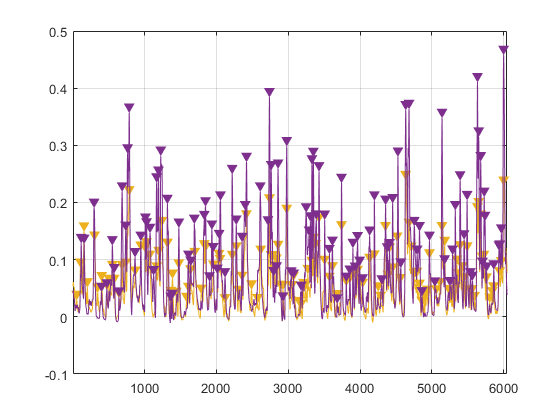

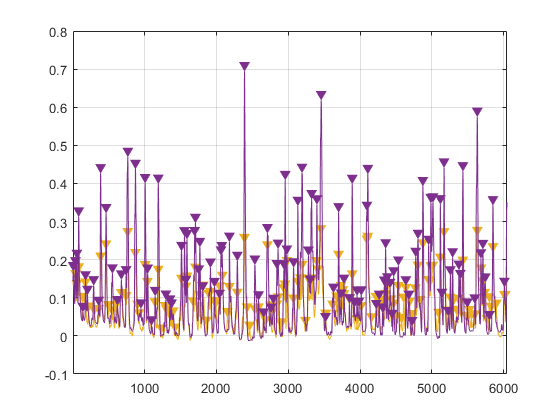

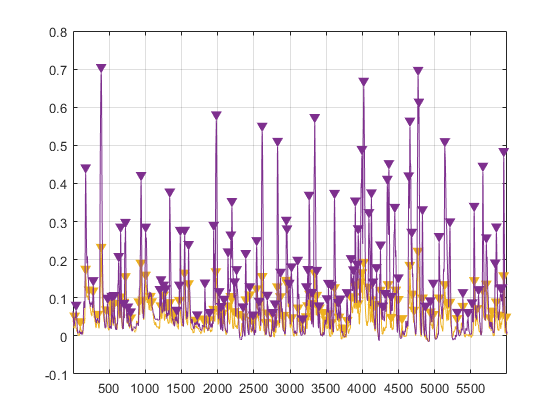

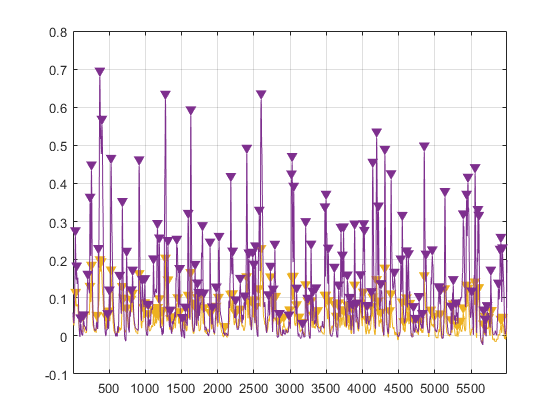

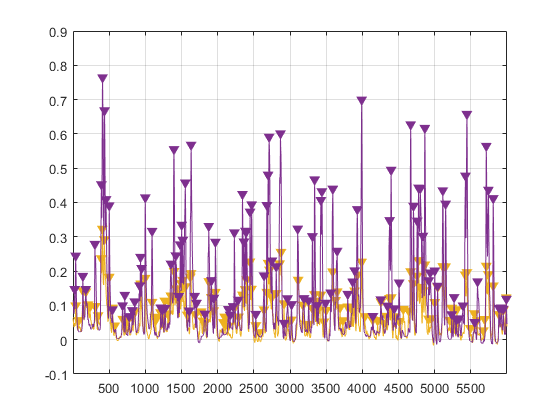

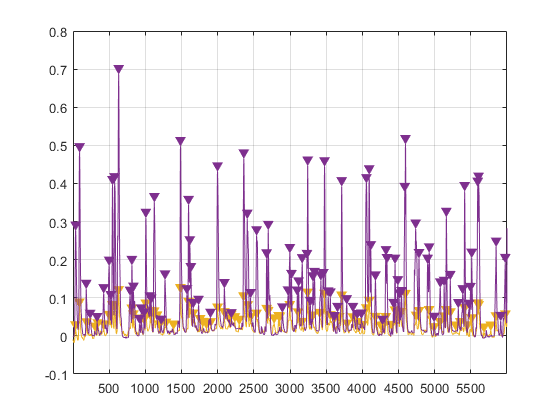

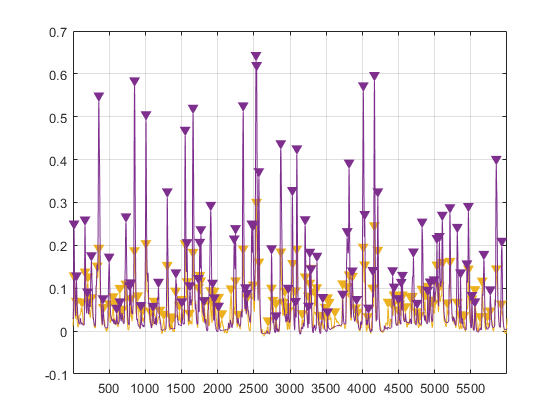

xcorrFiles = loadFileList([dname '*_corr.mat']);
m = size(xcorrFiles,1);

for i=1:m
    load(xcorrFiles{i});
    threshold = 0.02;
    
    FoIC = prctile(ICsignal,5);
    FoAC = prctile(ACsignal,5);
    ICdF = smooth((ICsignal - FoIC) / FoIC,5);
    ACdF = smooth((ACsignal - FoAC) / FoAC,5);
    figure; plot(ACdF); hold on; plot(ICdF);
    findpeaks(ICdF,'MinPeakProminence',0.01);
    findpeaks(ACdF,'MinPeakProminence',0.02);
    [pks, locs] = findpeaks(ICdF,'MinPeakProminence',0.01);
    [pks2, locs2] = findpeaks(ACdF,'MinPeakProminence',0.02);
    
    ICbin = []; ACbin = [];
    ICbin = zeros(size(ICdF));
    ICbin(locs) = 1;
    convP = ones(1,10);
    ICbin = conv(ICbin,convP);
    ICbin(ICbin > 0) = 3;
    ACbin = zeros(size(ICdF));
    ACbin(locs2) = 1;
    ACbin = conv(ACbin,convP);
    ACbin(ACbin > 0) = 5;
    coin = ACbin + ICbin;
    
    coinlbl = bwlabel(coin);
    events = table();
    for j = 1:max(coinlbl)
        class = max(coin(find(coinlbl==j)))
        if class == 8
            events = [events; table(j,1)]; %both
        elseif class == 5
            events = [events; table(j,2)]; %AC
        elseif class == 3
            events = [events; table(j,3)]; %IC
        end
    end
    events.Properties.VariableNames = {'EventNum','classification'};
    eventCell{i} = events;
end

## analysis 2


groupBothOAC = [];
for i=1:size(eventCell,2)
    events = eventCell{i};
    numBoth = size(events(events.classification == 1,:),1);
    numAC = size(events(events.classification == 2,:),1);
    groupBothOAC(i) = numBoth/(numAC+numBoth);
end
mean(groupBothOAC)

ans = 0.7996

sterr(groupBothOAC,2)

ans = 0.0306

## Movement Analysis

%load cells
cellList = loadFileList('.\Data\IC_A1_Window\*data.mat');
%cellStruct = struct();
for i = 1:size(cellList,1)
  [h] = load(cellList{i});
   names = fieldnames(h);
   temp = h.(names{1});
   if i == 1
    cellStruct(1) = temp;
   else
    cellStruct(i) = temp;
   end
end

## time series of mvmt versus normal event

file = 'Experiment-1538_AC.tif';
list = loadFileList(['.\Data\*\' file]);
img = loadTif(list{1},32);


listimg = loadFileList(['.\Data\*\*AC.tif']);

for i=1:size(list,1)
    temp = cellStruct(i);
    [fp,name,ext] = fileparts(listimg{i});
    img = loadTif(list{i},32);
    mvmtFrames = [];
    times = temp.mvmtTimes
    for j = 1:size(temp.mvmtTimes,1)
        if times(j,1) ~= 0
            mvmtFrames(:,:,:,j) = img(:,:,times(j,1):times(j,2));
        end
    end
    meanMvmtMovie = single(mean(mvmtFrames,4));
    writeTif(meanMvmtMovie,[fp '\' name '_mvmt.tif'],32)
    
    times = temp.ICeventlocs
    time_before = 30;
    time_after = 60;
    mvmtFramesIC = [];
    for j = 1:size(temp.ICeventlocs,2)
        mvmtFramesIC(:,:,:,j) = img(:,:,times(j)-time_before:times(j)+time_after);
    end
    meanICMovie = single(mean(mvmtFramesIC,4));
    writeTif(meanICMovie,[fp '\' name '_IC.tif'],32)
    
end

times =         1162        1252
        3300        3390
        5889        5979
        7138        7228
        7351        7441
        7384        7474
        7806        7896


times =           45         129         238         302         353         393         475         642         738         816         919        1021        1050        1198        1286        1465        1507        1552        1608        1638        1725        1909        2081        2133        2160        2266        2328        2364        2516        2606        2712        2788        2827        2893        3042        3111        3199        3252        3384        3482        3544        3588        3682        3718        3760        3809        3972        4029        4068        4135


times =         3854        3944
        6711        6801
        7912        8002
        7959        8049
        7996        8086
        8410        8500
        8540        8630
       10892       10982


times =           59          89         186         311         400         461         524         551         635         751         841        1027        1204        1248        1318        1369        1454        1513        1619        1678        1758        1900        1958        2039        2099        2117        2158        2206        2276        2376        2400        2452        2555        2657        2739        2799        2876        2892        2962        3070        3239        3269        3342        3403        3559        3578        3712        3839        3874        3945


times =          253         343
        1165        1255
        1407        1497
        1477        1567
        1989        2079
        2732        2822
        3060        3150
        3179        3269
        3260        3350
        3303        3393


times =           81         109         156         230         298         454         497         571         634         665         706         792         851         886         935        1030        1081        1158        1199        1321        1345        1401        1434        1484        1585        1706        1720        1750        1818        1861        1918        1981        2133        2182        2282        2336        2409        2429        2451        2483        2506        2537        2640        2684        2729        2767        2944        2982        3068        3122


times =            0           0
         221         311
         315         405
        1248        1338
        1459        1549
        1871        1961
        2469        2559
        2950        3040
        3002        3092
        3796        3886


times =           70         169         213         254         305         393         456         559         590         666         692         710         734         793         896         933         977        1049        1167        1215        1403        1418        1440        1505        1536        1589        1615        1716        1837        1871        1901        1990        2007        2048        2081        2200        2247        2337        2423        2470        2500        2560        2699        2767        2874        2926        2964        2987        3021        3176


times =         1179        1269
        1805        1895
        3822        3912
        3950        4040
        5704        5794


times =          177         258         341         379         438         468         513         533         698         747         807         849         900         961        1041        1080        1116        1258        1327        1441        1536        1566        1613        1692        1855        2042        2173        2208        2238        2345        2436        2474        2528        2649        2680        2779        2831        2871        2923        3130        3180        3248        3293        3338        3452        3504        3550        3635        3774        3861


times =           71         161
         295         385
         663         753
         897         987
        1572        1662
        2614        2704
        3818        3908
        4540        4630
        4727        4817
        5337        5427


times =           36         102         232         330         369         510         599         674         793         813         849         902         932        1075        1106        1139        1354        1429        1473        1539        1653        1847        1933        2169        2237        2381        2534        2558        2695        2833        2944        3193        3266        3298        3436        3538        3742        3794        3850        3875        3996        4066        4188        4282        4347        4386        4548        4640        4759        4885


times =         1148        1238
        2707        2797
        3244        3334
        3289        3379
        3331        3421
        4011        4101
        4110        4200
        4181        4271
        4469        4559
        4605        4695


times =           34         233         290         364         527         639         661         701         842         898         948         999        1100        1180        1304        1367        1454        1553        1667        1733        1786        1953        2007        2153        2230        2346        2439        2562        2653        2776        2929        2992        3073        3160        3194        3218        3281        3403        3504        3674        3728        3888        3958        3990        4048        4112        4158        4225        4344        4469


%% 
listimg = loadFileList(['.\Data\*\*AC_IC.tif']);
totalimg = [];
for i = 1:size(listimg,1)
    img = loadTif(listimg{i},32);
    totalimg = [totalimg img];
end

listimg = loadFileList(['.\Data\*\*AC_mvmt.tif']);
totalimg2 = [];
for i = 1:size(listimg,1)
    img = loadTif(listimg{i},32);
    totalimg2 = [totalimg2 img];
end

listimg = loadFileList(['.\Data\*\*AC_IC.tif']);
listimgAC = loadFileList(['.\Data\*\*AC_mvmt.tif']);

i = 3;
ACICimg = loadTif(listimg{i},32);
ACmvtimg = loadTif(listimgAC{i},32);
count = 1;
cax = [-.05 .5]

cax =    -0.0500    0.5000


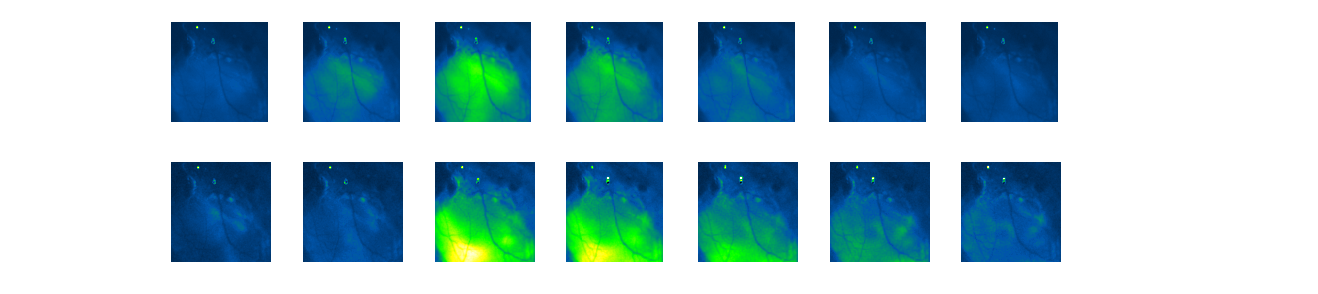

Undefined function or variable 'ACs'.

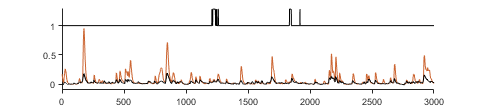

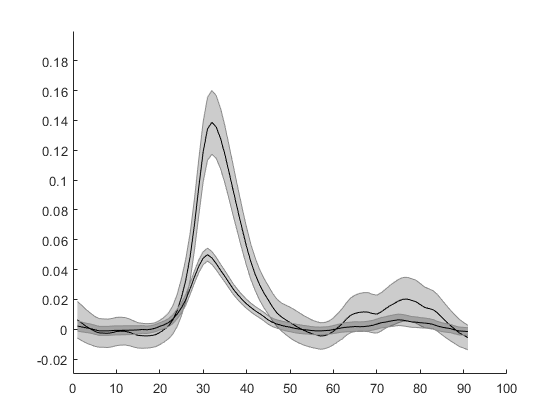

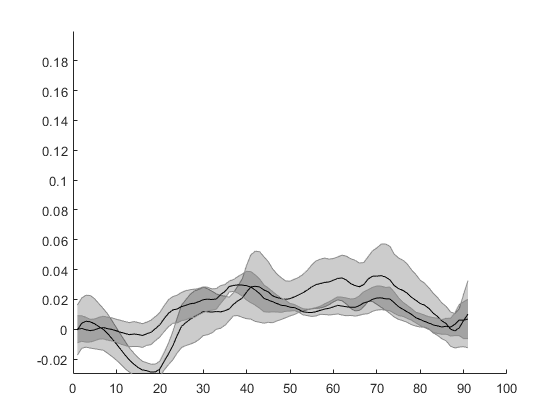

figure;
for i = 21:5:51
   subplot(2,8,count);
    imagesc(ACICimg(:,:,i));
    colormap gfb;
    caxis(cax);
    axis off;
   subplot(2,8,8+count);
    imagesc(ACmvtimg(:,:,i+5));
    colormap gfb;
    caxis(cax);
    axis off;
    truesize;
   count = count + 1;
end

export_fig(['.\EPS Panels\IC_movement.eps'], '-eps', '-nocrop');

lims = [400:2400]

lims =    400   401   402   403   404   405   406   407   408   409   410   411   412   413   414   415   416   417   418   419   420   421   422   423   424   425   426   427   428   429   430   431   432   433   434   435   436   437   438   439   440   441   442   443   444   445   446   447   448   449


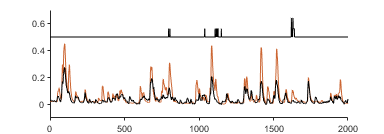

temp = cellStruct(3); l_red = [204 102 51]/255;
figure;
plot((cellStruct(3).norms(lims)-1)*.10+.5,'Color','k'); hold on;
plot(cellStruct(3).ACsignal(lims),'Color',l_red);
plot(cellStruct(3).ICsignal(lims),'Color','k');
ylim([-.1 0.7])
xlim([0 2000])
%plot(cellStruct(5).hits(1:3000));
figQuality(gcf,gca,[4 1.4]);
export_fig(['.\EPS Panels\exampleTimeSeries_mvmt.eps'], '-eps', '-nocrop');


figure;
time = 1:1:91;
ACIC = mean(temp.ACeventsIC,1);
ICIC = mean(temp.ICeventsIC,1)

ICIC =     0.0363    0.0361    0.0357    0.0353    0.0351    0.0353    0.0350    0.0348    0.0344    0.0341    0.0339    0.0340    0.0342    0.0342    0.0343    0.0345    0.0350    0.0363    0.0379    0.0395    0.0415    0.0441    0.0475    0.0521    0.0579    0.0645    0.0718    0.0800    0.0885    0.0943    0.0970    0.0947    0.0903    0.0846    0.0785    0.0722    0.0667    0.0619    0.0571    0.0531    0.0495    0.0461    0.0435    0.0418    0.0404    0.0389    0.0380    0.0375    0.0369    0.0365


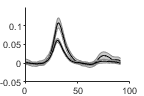

shadedErrorBar(time,ACIC-mean(ACIC(1:10)),sterr(temp.ACeventsIC,1),'transparent',true); %,lineProps,transparent
shadedErrorBar(time,ICIC-mean(ICIC(1:10)),sterr(temp.ICeventsIC,1),'transparent',true); %,lineProps,transparent

ylim([-.05 0.15])
figQuality(gcf,gca,[1.5 1])
print(['.\EPS Panels\AC_IC_printed.pdf'],'-dpdf')

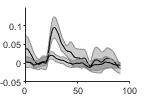


figure;
time = 1:1:91;
ACmvmt = mean(temp.ACdata,2);
ICmvmt = mean(temp.ICdata,2);
shadedErrorBar(time,ACmvmt-mean(ACmvmt(10:20)),sterr(temp.ACdata,2),'transparent',true); %,lineProps,transparent
shadedErrorBar(time,ICmvmt-mean(ICmvmt(1:10)),sterr(temp.ICdata,2),'transparent',true);
ylim([-.05 0.15])
figQuality(gcf,gca,[1.5 1])
print(['.\EPS Panels\AC_mvmt_printed.pdf'],'-dpdf')

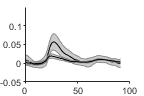

%Group Average
ACs_IC = [];
ACs_mvmt = [];
ICs_IC = [];
ICs_mvmt = [];

for i=1:size(cellStruct,2)
    ACs_IC(:,i) = mean(cellStruct(i).ACeventsIC,1)';
    ICs_IC(:,i) = mean(cellStruct(i).ICeventsIC,1)';
    ACs_mvmt(:,i) = mean(cellStruct(i).ACdata,2);
    ICs_mvmt(:,i) = mean(cellStruct(i).ICdata,2);
    
end

figure;
time = 1:1:91;
ACmvmt = mean(ACs_mvmt,2);
ICmvmt = mean(ICs_mvmt,2);
shadedErrorBar(time,ACmvmt-mean(ACmvmt(10:20)),sterr(ACs_mvmt,2),'transparent',true); %,lineProps,transparent
shadedErrorBar(time,ICmvmt-mean(ICmvmt(1:10)),sterr(ICs_mvmt,2),'transparent',true); %,lineProps,transparent
ylim([-.05 0.15])
figQuality(gcf,gca,[1.5 1])
print(['.\EPS Panels\group_AC_mvmt_printed.pdf'],'-dpdf')

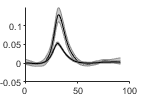


figure;
time = 1:1:91;
ACsIC = mean(ACs_IC,2);
ICsIC = mean(ICs_IC,2);
shadedErrorBar(time,ACsIC-mean(ACsIC(1:10)),sterr(ACs_IC,2),'transparent',true); %,lineProps,transparent
shadedErrorBar(time,ICsIC-mean(ICsIC(1:10)),sterr(ICs_IC,2),'transparent',true); %,lineProps,transparent
ylim([-.05 0.15])
figQuality(gcf,gca,[1.5 1])
print(['.\EPS Panels\group_AC_IC_printed.pdf'],'-dpdf')

%Panel

ICfreqs = [cellStruct.ICeventFreq];
ACfreqs = [cellStruct.ACeventFreq];
mvmtfreqs = [cellStruct.mvmtFreq];

meanMarkSize = 15;
markSize = 10;
m = size(ICfreqs,2)

m = 7

m2 = size(ACfreqs,2);
m3 = size(mvmtfreqs,2);
l_grey = [0.7 0.7 0.7];
group1 = ICfreqs';
group2 = ACfreqs';
group3 = mvmtfreqs';

       mean1 = mean(group1,1);
       std1 = sterr(group1,1);
       mean2 = mean(group2,1);
       std2 = sterr(group2,1);
       mean3 = mean(group3,1);
       std3 = sterr(group3,1);
       
       h = figure;
       scatter(1*ones(m,1), group1,markSize,l_grey,'filled'); hold on;
       scatter(2*ones(m2,1), group2,markSize,l_grey,'filled');
       scatter(3*ones(m3,1), group3,markSize,l_grey,'filled');
       errorbar([1], mean1, std1,'LineStyle', 'none','LineWidth',1,'Color','k','CapSize',0,'Marker','.','MarkerSize',meanMarkSize);
       errorbar([2], mean2, std2,'LineStyle', 'none','LineWidth',1,'Color','r','CapSize',0,'Marker','.','MarkerSize',meanMarkSize);
       errorbar([3], mean3, std3,'LineStyle', 'none','LineWidth',1,'Color','k','CapSize',0,'Marker','.','MarkerSize',meanMarkSize);
       xlim([0.25 3.75]);
       xticks([1 2 3]);
       %xticklabels(conditions);
       %ylabel(ylbl);
       [h2,p] = ttest2(group1,group2)

h2 = 1

p = 0.0031

       [h,p] = ttest2(group1,group3)

h = 1

p = 8.4620e-09

       [h,p] = ttest2(group2,group3)

h = 1

p = 3.6997e-09

       pt(5) = p;
       disp(p);

   3.6997e-09




       figQuality(gcf,gca,[0.7 1.7]);
       ylim([0 15])
       export_fig(['.\EPS Panels\EventFrequency.eps'], '-eps', '-nocrop');
       print(['.\EPS Panels\EventFreq    _printed.pdf'],'-dpdf');

%
file = '.\Data\Sally Fig\exampleTraces.fig';
figure;
fig = openfig(file,'new','visible');

test = gca;
for i=1:size(test.Children,1)
 if strcmp(test.Children(i).Marker,'o')
     test.Children(i).MarkerFaceColor = 'flat';
     test.Children(i).SizeData = 1;
 
 end
end
 
figQuality(gcf,gca,[1.9 1.4]);
export_fig('.\EPS Panels\FlouTraces.eps','-eps')

file = '.\Data\Sally Fig\exampleTraces.fig';
figure;
fig = openfig(file,'new','visible');

test = gca;
for i=1:size(test.Children,1)
 if strcmp(test.Children(i).Marker,'o')
     test.Children(i).MarkerFaceColor = 'flat';
     test.Children(i).SizeData = 1;
 
 end
end
 
figQuality(gcf,gca,[1.9 1.4]);
export_fig('.\EPS Panels\FlouTraces.eps','-eps')
  

## Model

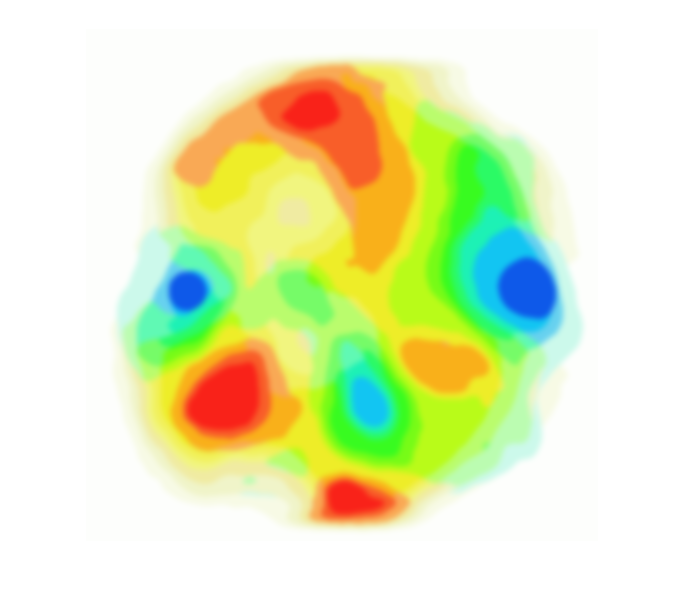

% generate a blank
img = imread('.\Data\raw_map_from_Johns_paper.bmp');
img = imresize(img,[512,512]);
[X,map] = rgb2ind(imgaussfilt(img,5),24,'nodither');
img = ind2rgb(X,map);

figure
imshow(imgaussfilt(img,3));

imwrite(imgaussfilt(img,3),'.\Data\cartoon_map.bmp')

img = imread('.\Data\rec_map_from_Johns_paper.bmp');
img = imresize(img,[512,512]);
[X,map] = rgb2ind(imgaussfilt(img,5),24,'nodither');
img = ind2rgb(X,map);